EE-414 Speech Processing Lab

 Lab-2 - 180020002

Problem Statement: A-a

Theory:

A signal is said to be stationary if its frequency or spectral contents are not changing with respect to time. Considering a sine wave of 10Hz and observing its magnitude spectrum, it can be seen that sine wave amplitude varies in the time domain, but its frequency content will have only one frequency component, that is, impulse at 10 Hz.

Mathematically, a singletone sine wave can be represented as:

$x\left(t\right)=\mathrm{Acos}\left(\omega t+\phi \right)$, where A is the amplitude, $\omega$ is the angular frequency and $\phi$ is phase.

Procedure:

The first step is to generate a singletone sine wave. A sine wave is characterized by its three parameters, namely, amplitude, frequency and phase. To study the concept of stationarity and non-stationarity, the frequency parameter is important and hence we consider maximum amplitude to be 1 and phase to be 0. On a digital machine the sine wave needs to be sampled for plotting or processing and the sampling frequency should be higher than the requirement of baseband sampling theorem. That is, sampling frequency should be more than twice the maximum frequency component for the case of sine wave. For smooth contour of sine wave, it is better to consider the sampling frequency to be much higher than the frequency of the sine wave. For instance, a 10 Hz sine wave sampled at 1000 Hz sampling frequency and for a duration of 1 sec can be generated in Matlab using the code given below.

The spectrum of the 10 Hz sine wave generated can be computed using the fast Fourier transform (FFT) command available in the Matlab. The signal is for 1 sec duration and hence has 1000 samples. For efficient computation, the next higher binary power is chosen, that is, 1024 point FFT can be used. A Matlab code for computing the spectrum is given below. The spectrum will be shown only for half portion, since the magnitude spectrum is symmetric with respect to origin. A peak at 10 Hz indicates presence of 10 Hz component in the signal.

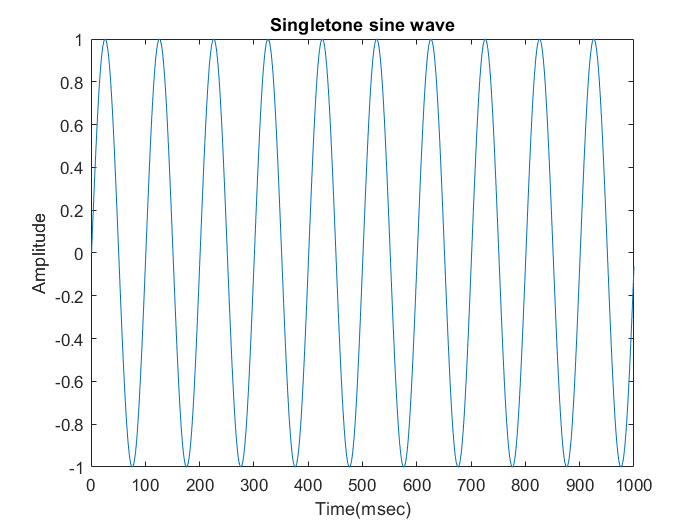

%MATLAB code to generate single tone wave of 10 Hz.
%Sine wave is assumed to be sampled using a sampling frequency
%of 1000 Hz and it is duration of 1 sec
t=0:1/1000:1;

%1000, indicates sampling frequency, the last argument 1 indicates the
%duration in seconds

y=sin(2*pi*10*t);
%sine wave of 10 Hz is generated using the above command

x=1:1000;

%figure to plot 10 Hz sine wave in time domain
plot(x,y(1:1000));
xlabel('Time(msec)');
ylabel('Amplitude');
title('Singletone sine wave');

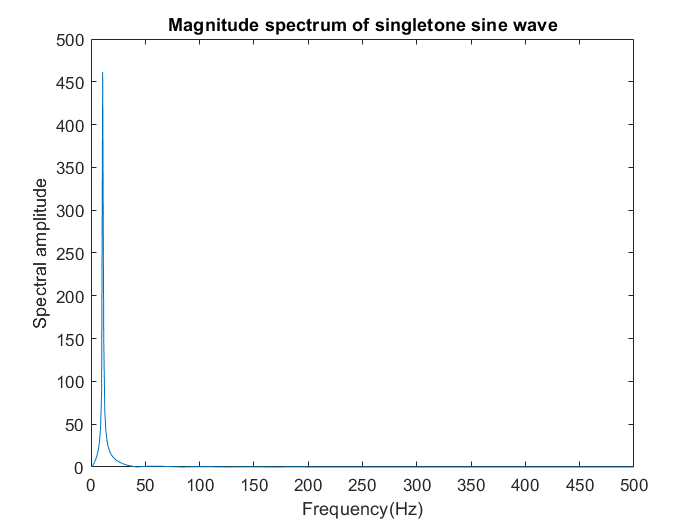


%MATLAB code to plot spectrum of single tone sine wave of 10 Hz.

Y=abs(fft(y,1024));
%the above command computes the magnitude spectrum of the sine wave
x=[1:1024]*(1000/1024);
%this command is to plot the values as a function of frequency
%The scaling factor ratio of 1000 refers to sampling frequency
%and 1024 refers to number of points for FFT computation.

%figure to plot magnitude spectrum of 10 Hz sine wave
plot(x(1:512),Y(1:512));
xlabel('Frequency(Hz)');
ylabel('Spectral amplitude');
title('Magnitude spectrum of singletone sine wave');

Problem Statement: B-a

Theory:

Next let us consider a multitone sine wave that contains many frequency components. If all the frequency components do not change with time, then without any consideration to the number of frequency components present, the multitone sine wave is still a stationary signal. Consider a multitone sine wave made of three frequency components namely, 10 Hz, 50 Hz and 100 Hz. Even though this signal looks complicated compared to the singletone sine wave it is still a stationary signal because, the frequency contents do not change with time.

 Mathematically, a multitone sine wave can be represented as:


$$x\left(t\right)=A_1 \mathrm{cos}\left(\omega_1 t+\phi_1 \right)+A_2 \mathrm{cos}\left(\omega_2 t+\phi_2 \right)+A_3 \mathrm{cos}\left(\omega_3 t+\phi_3 \right)\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp$$


Procedure:

On the similar lines described for singletone sine wave, a multitone sine wave can be generated. The only difference is that the number of frequency components are more than one. For better visualization, the sampling frequency should be much higher than the highest frequency component. For instance, a multitone sine wave made of 10, 50 and 100 Hz frequency components can be generated using the Matlab code given below. The shape of the signal that will be generated is relatively more complicated compared to the single tone case. Hence it becomes difficult to find the frequency components by direct measurement in the time domain. However, the important point is, all the frequency components are present at all instants of time. Hence the multitone sine wave that will be generated by this program will also be a stationary signal.

To observe the different frequency components, the discrete Fourier transform (DFT) can be computed using FFT for the entire sequence. A Matlab code for the same is given below. On executing this program, a magnitude spectrum showing peaks at 10, 50 and 100 Hz will be generated.

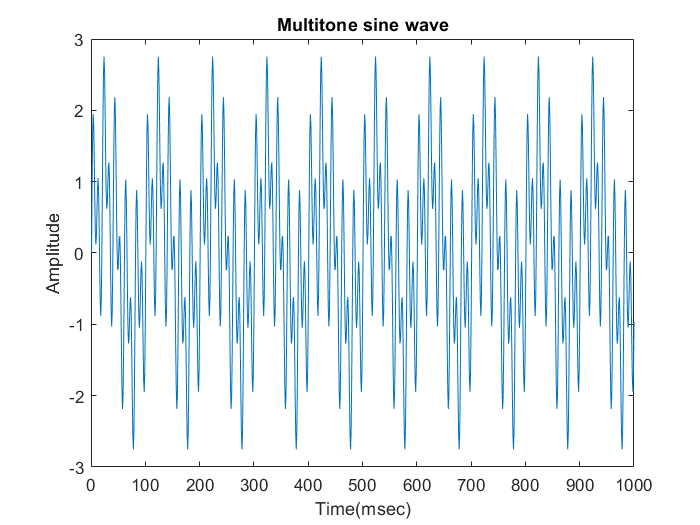

%MATLAB code to generate multitone sinewave
%Sine wave is assumed to be sampled using a sampling frequency
%of 1000 Hz and it is duration of 1 sec

%command to generate samples
t=0:1/1000:1;

%generation of 10 Hz sine wave sampled at 1000 Hz
y1=sin(2*pi*10*t);
%generation of 50 Hz sine wave sampled at 1000 Hz
y2=sin(2*pi*50*t);
%generation of 100 Hz sine wave sampled at 1000 Hz
y3=sin(2*pi*100*t);

%genaration of multitone sine wave made of 10,50 and 100 Hz componenets
y=y1+y2+y3;

x=1:1000;
%command to plot multitone sinewave in time domain

plot(x,y(1:1000));
xlabel('Time(msec)');
ylabel('Amplitude');
title('Multitone sine wave');

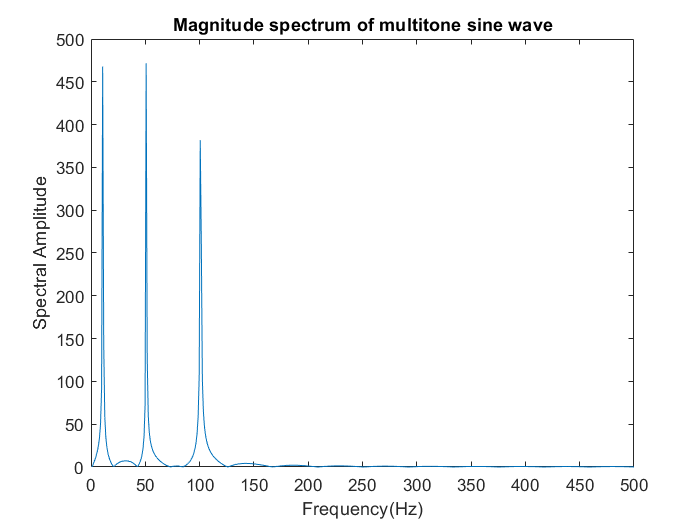


%MATLAB code to plot magnitude spectrum of multitone sine wave

%command to generate magnitude spectrum
Y=abs(fft(y,1024));

x=[1:1024]*(1000/1024);

%command to plot magnitude spectrum 

plot(x(1:512),Y(1:512));
xlabel('Frequency(Hz)');
ylabel('Spectral Amplitude');
title('Magnitude spectrum of multitone sine wave');

Problem Statement: C-a,b

Theory:

From this point onwards we deviate to introduce the concept of non-stationarity. Let us consider a multitone sine wave whose duration is equally divided into four intervals. Let the frequency component of f1 Hz be present in the first interval, then two components of f1 and f2 Hz in the second interval, three components of f1, f2 and f3 Hz for the third interval and finally f1 Hz in the fourth interval. Now if we observe this signal for its entire duration, the frequency components are changing from one interval to the other. Thus such a signal qualifies the definition of non-stationarity and hence is an example for a non-stationary signal. Therefore this signal is more opt to be termed as non-stationary multitone sine wave. For instance, consider a non-stationary multitone sine wave of duration 1 sec which has 10 Hz component for 0-250 msec, 10 and 50 Hz components for 250-500 msec, 10, 50 and 100 Hz components for 500-750 msec and only 10 Hz component for 750-1000 msec. Such a signal qualifies the definition of non-stationarity, since the frequency contents change from one interval to other. A mathematical formulation for the just described signal can be written as:


$$\begin{array}{l}
x\left(t\right)=A_1 \mathrm{cos}\left(\omega_1 t+\phi_1 \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0\le t\le t_1 \\
\;\;\;\;\;\;\;\;=A_1 \mathrm{cos}\left(\omega_1 t+\phi_1 \right)+A_2 \mathrm{cos}\left(\omega_2 t+\phi_2 \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;t_1 \le t\le t_2 \\
\;\;\;\;\;\;\;\;=A_1 \mathrm{cos}\left(\omega_1 t+\phi_1 \right)+A_2 \mathrm{cos}\left(\omega_2 t+\phi_2 \right)+A_3 \mathrm{cos}\left(\omega_3 t+\phi_3 \right)\;\;\;\;\;\;\;\;\;\;\;\;t_2 \le t\le t_3 \\
\;\;\;\;\;\;\;\;=A_1 \mathrm{cos}\left(\omega_1 t+\phi_1 \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;t_3 \le t\le t_4 
\end{array}$$


Procedure:

The next step is to generate a non-stationary signal. A simple way of generating such signal is to use different combinations of the single tone components available. A Matlab code to generate a non-stationary multitone sine wave made of different combinations of 10, 50 and 100 Hz components is given below. The shape of the waveform will be different in different regions indicating the change in frequency components.

First we generate the frequency spectrum taking the whole signal at once. 

The spectrum of the non-stationary signal will be meaningful if it is computed over regions that can be treated as stationary. For instance, the whole signal can be divided into four stationary regions and hence each region can be considered separately for computing the magnitude spectrum. A Matlab code to generate magnitude spectra of different stationary regions of the non-stationary signal generated above is given below.

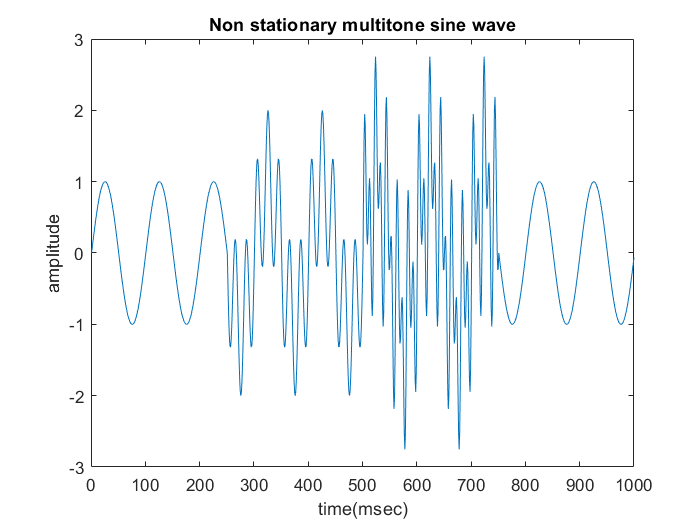

%Matlab program to generate non-stationary multitone sine wave
%Signal is assumed to be sampled at 1000Hz and for a 
%duration of 1 sec.

%Individual sinewave are generated  
t=0:1/1000:1;
y1=sin(2*pi*10*t);
y2=sin(2*pi*50*t);
y3=sin(2*pi*100*t);

%some combination of sinewaves are generated
z1=y1+y2;
z2=y1+y2+y3;

%Non-stationary signal is generated 
%First 250 samples contain 10 Hz
%First 250 samples contain 10 Hz and 50 Hz
%First 250 samples contain 10 Hz, 50 Hz and 100 Hz
%First 250 samples contain 10 Hz
y=[y1(1:250),z1(251:500),z2(501:750), y1(751:1000)];

x=[1:1000];
%command to plot non-stationary multitone sinewave in time domain

plot(x,y(1:1000));
xlabel('time(msec)');
ylabel('amplitude');
title('Non stationary multitone sine wave');

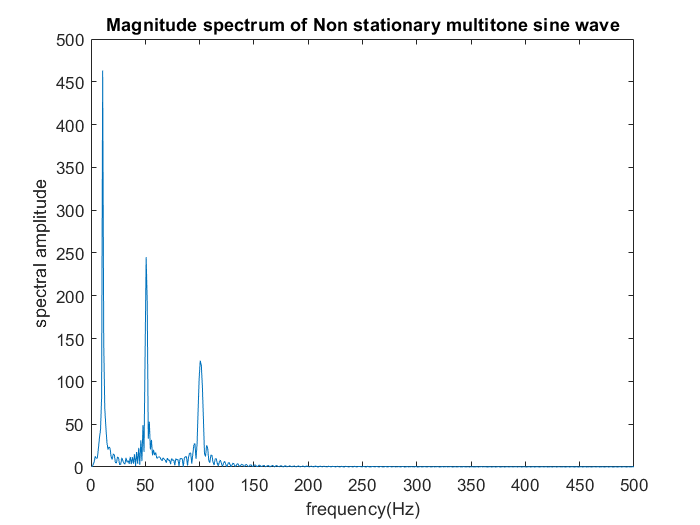


%Scilab program to generate the magnitude spectra of non-stationary multitone sine wave taking
%whole signal at once
Y=abs(fft(y,1024));
x=[1:1024]*(1000/1024);

plot(x(1:512),Y(1:512));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of Non stationary multitone sine wave');

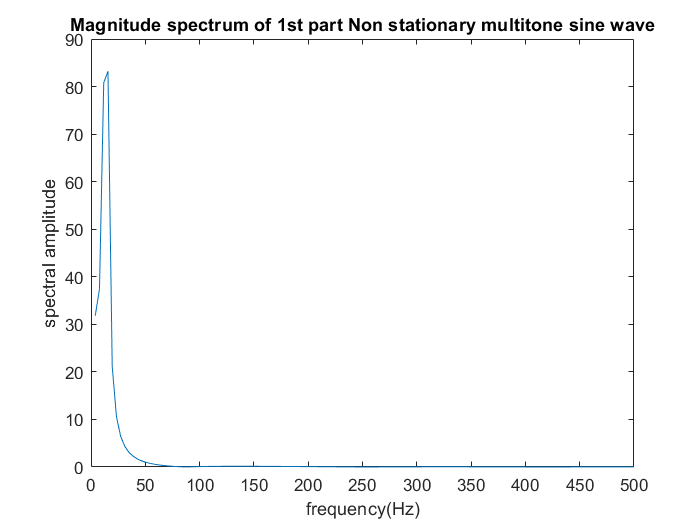


%Scilab program to generate the magnitude spectra of non-stationary multitone sine
%wave in four stationary regions
x=[1:256]*(1000/256);

Y1=abs(fft(y1(1:250),256));

plot(x(1:128),Y1(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of 1st part Non stationary multitone sine wave');

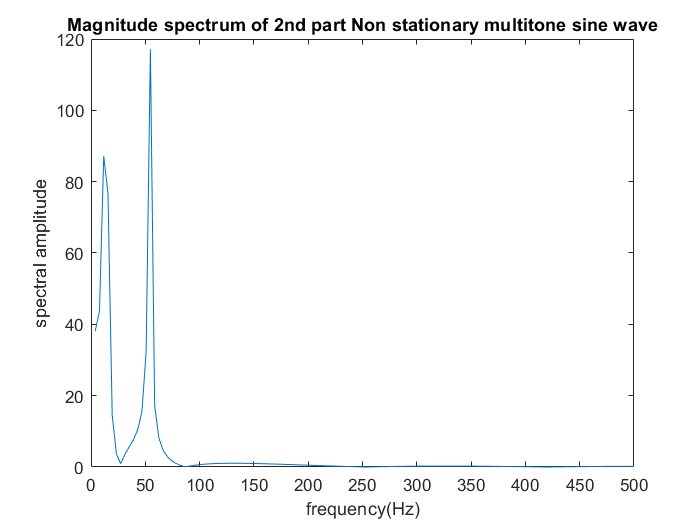


Y2=abs(fft(z1(251:500),256));

plot(x(1:128),Y2(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of 2nd part Non stationary multitone sine wave');

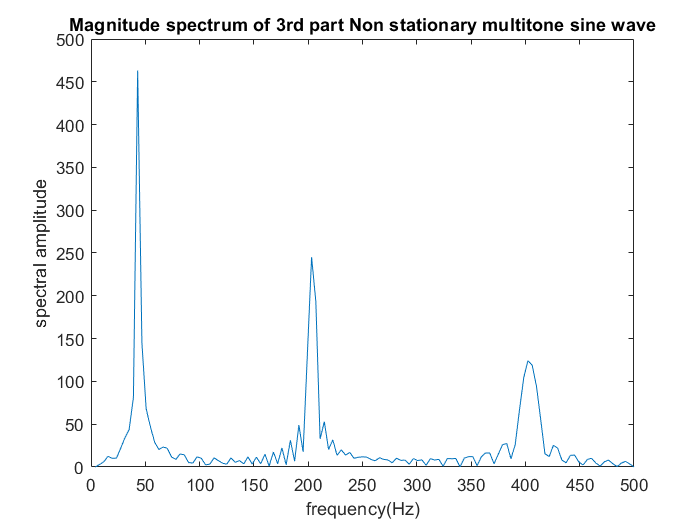


Y3=abs(fft(z2(501:750),256));

plot(x(1:128),Y(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of 3rd part Non stationary multitone sine wave');

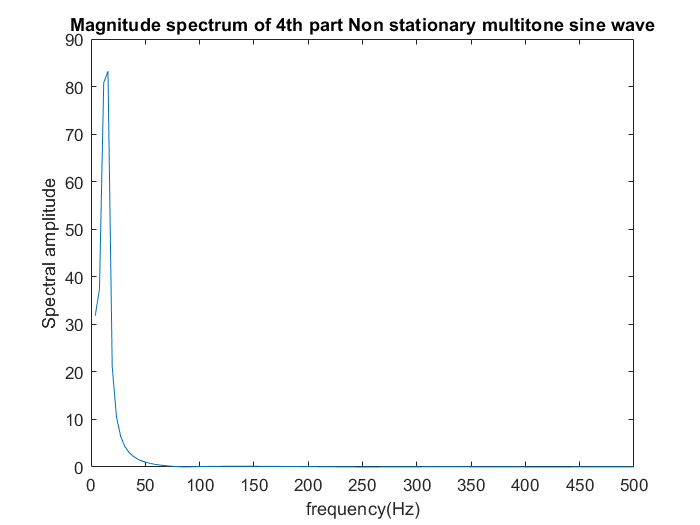


Y4=abs(fft(y1(751:1000),256));

plot(x(1:128),Y4(1:128));
xlabel('frequency(Hz)');
ylabel('Spectral amplitude');
title('Magnitude spectrum of 4th part Non stationary multitone sine wave');

Observations:

We observe that while taking frequency spectrum plot of the whole signal at once and later taking the plots for the different stationary regions, we are not able to capture the variations in the frequencies with respect to time in the whole signal case. This is a limitation of Fourier Transform. The solution is to use spectrograms to capture the variations in the frequencies with respect to time.

Problem Statement: D-a,b

Theory:

Finally, the speech signal is a much more complicated non-stationary signal compared to the one described above. Speech signal differs in two aspects from the non-stationary multitone sine wave. First, there may not be just one, two or three components, but many more in a given interval of time. Second, the interval itself will be very short, as short as about 10-30 msec as against 250 msec considered. To summarize, the frequency contents of the speech signal will have many frequency contents and these components change continuously with time. Consider a speech signal for the phrase ‘**Sakshaat Speech Processing**’ .The changing frequency components can also be observed. A mathematical approximation to the speech signal to indicate its non-stationarity can be given as:


$$x\left(t\right)={\sum A}_k \left(t\right)\mathrm{cos}\left(\omega_k \left(t\right)t+\phi_k \left(t\right)\right)\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp$$


Procedure:

The speech signal can be recorded using microphone as a transducer and sampled and stored using suitable sampling frequency. Such a digitized version of the speech signal will be stored in file and mostly used format is the wav format. Such a signal can be plotted in the time domain to observe the time varying characteristics of the signal. A Matlab code to load the speech signal stored in a wave format and plotting its waveform is given below.

The speech signal can be assumed to be stationary for all practical processing point of view when it is considered in blocks of 10-30 msec. The spectrum of any portion of speech signal can be computed using FFT by viewing it in blocks of 10-30 msec. A matlab code for computing the spectra of selected portions is given below.

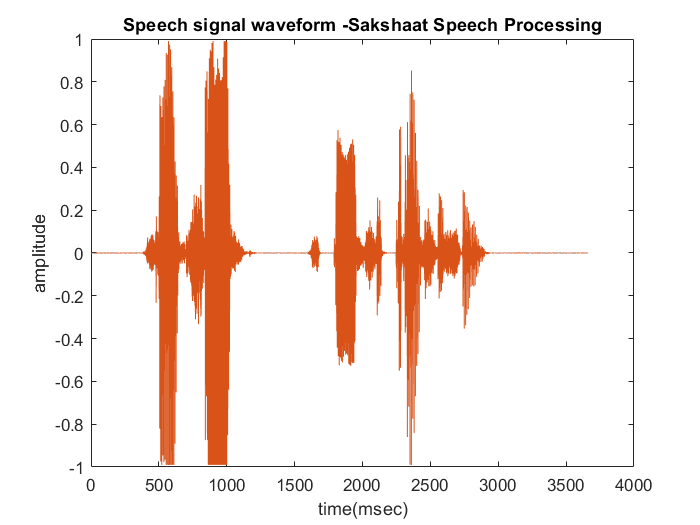

%Matlab program to load and plot waveform of speech signal stored in
% wav file format
%file name is sakshat_speech_processing.wav and full path is given
[y,fs]=audioread('sakshat_speech_processing.wav');
audiowrite('sakshat_speech_processing_new.wav',y,8000);
[y,fs]=audioread('sakshat_speech_processing_new.wav');

%normalising the signal amplitudes to be in -1 to 1
y=y./(1.01*abs(max(y)));
%plotting waveform of the speech signal
x=([1:length(y)]/44100)*1000;
plot(x,y);
xlabel('time(msec)');
ylabel('amplitude');
title('Speech signal waveform -Sakshaat Speech Processing');

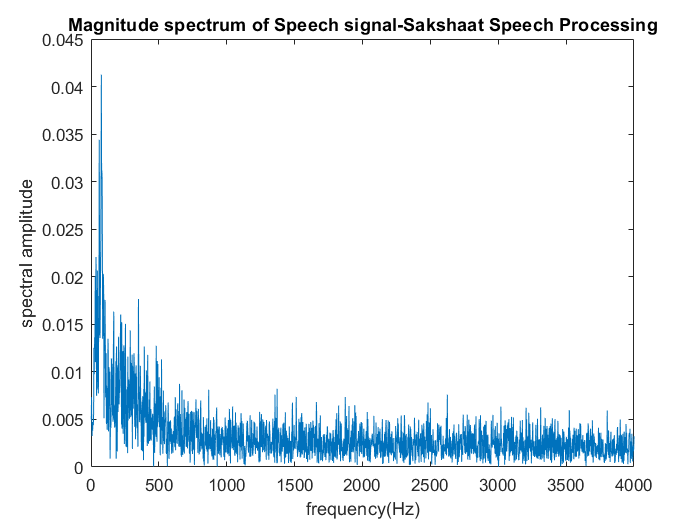

Y=abs(fft(y,4096));
x=[1:4096]*(8000/4096);

plot(x(1:2048),Y(1:2048));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of Speech signal-Sakshaat Speech Processing');

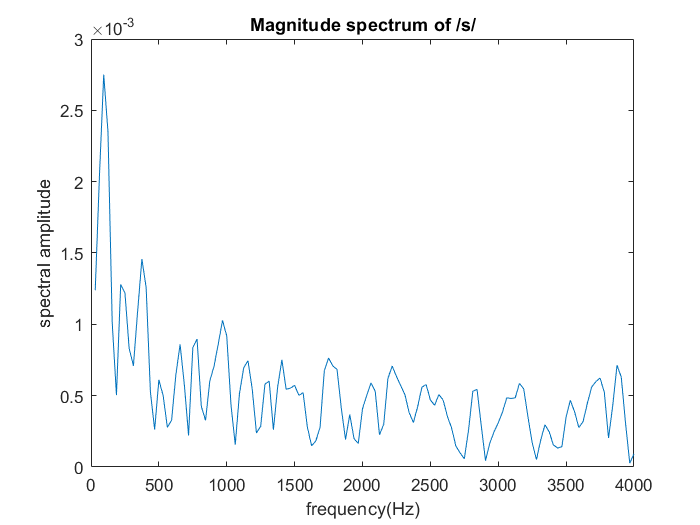

%sound-/s/
x=[1:256]*(8000/256);

Y1=abs(fft(y(356:461),256));

plot(x(1:128),Y1(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /s/');

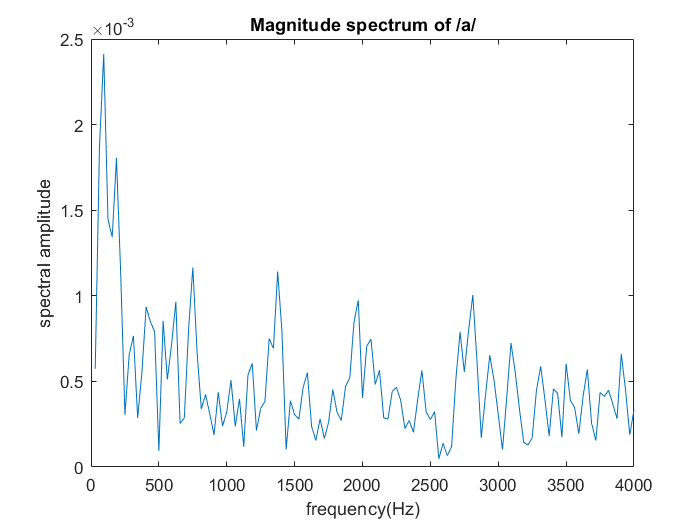


%sound-/a/
x=[1:256]*(8000/256);

Y2=abs(fft(y(461:589),256));

plot(x(1:128),Y2(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /a/');

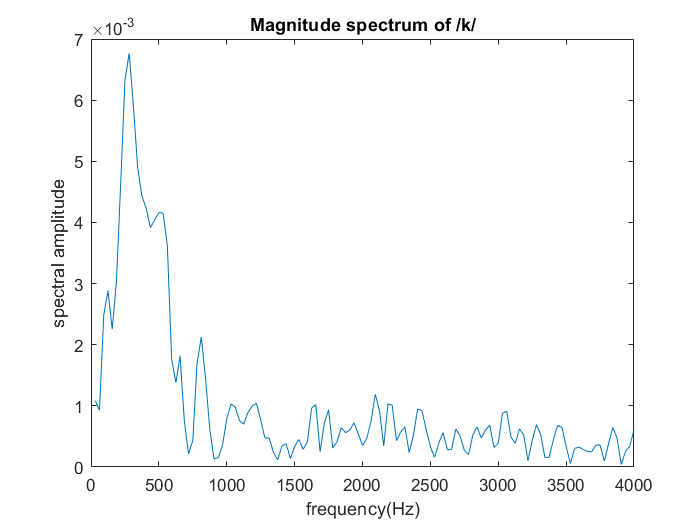


%sound-/k/
x=[1:256]*(8000/256);

Y3=abs(fft(y(589:699),256));

plot(x(1:128),Y3(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /k/');

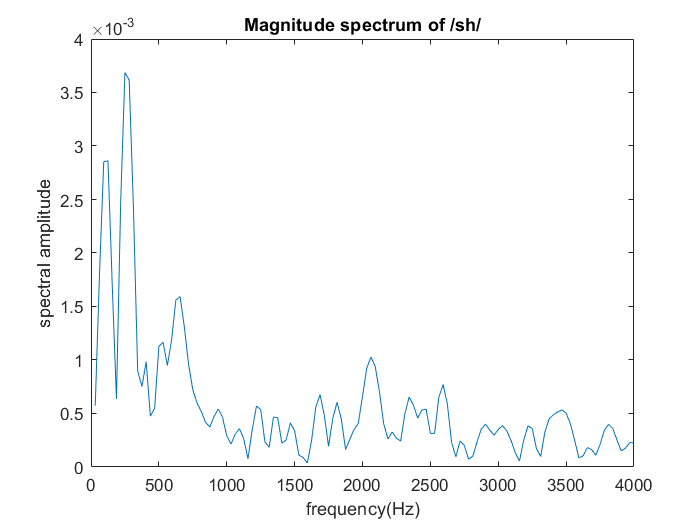


%sound-/sh/
x=[1:256]*(8000/256);

Y4=abs(fft(y(699:772),256));

plot(x(1:128),Y4(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /sh/');

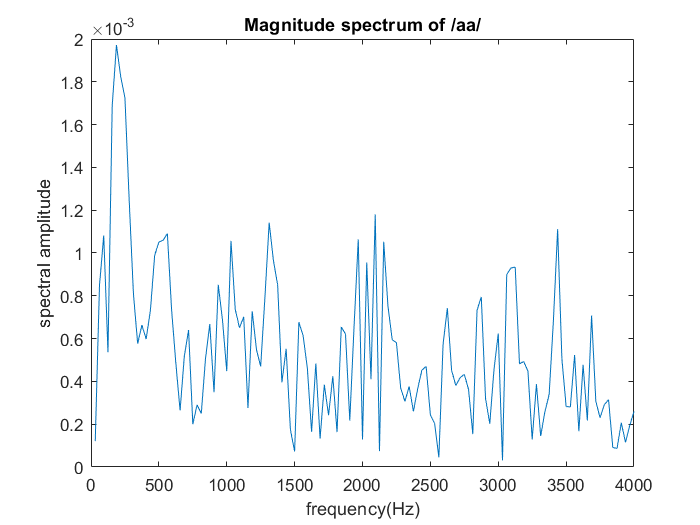


%sound-/aa/
x=[1:256]*(8000/256);

Y5=abs(fft(y(772:925),256));

plot(x(1:128),Y5(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /aa/');

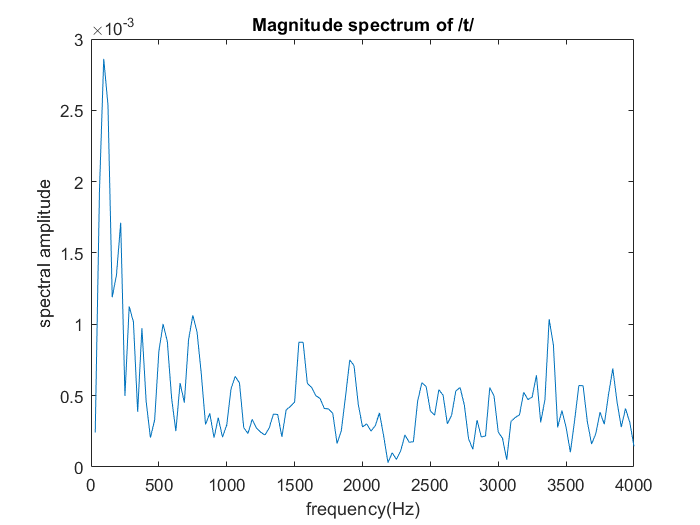


%sound-/t/
x=[1:256]*(8000/256);

Y6=abs(fft(y(925:1040),256));

plot(x(1:128),Y6(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /t/');

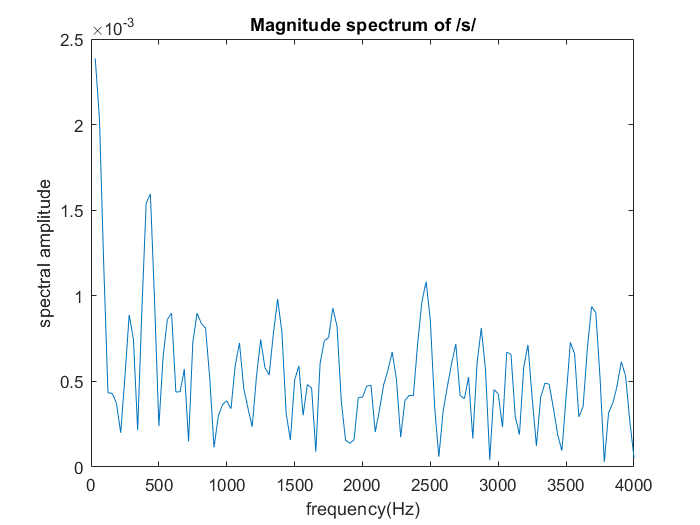


%sound-/s/
x=[1:256]*(8000/256);

Y7=abs(fft(y(1431:1547),256));

plot(x(1:128),Y7(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /s/');

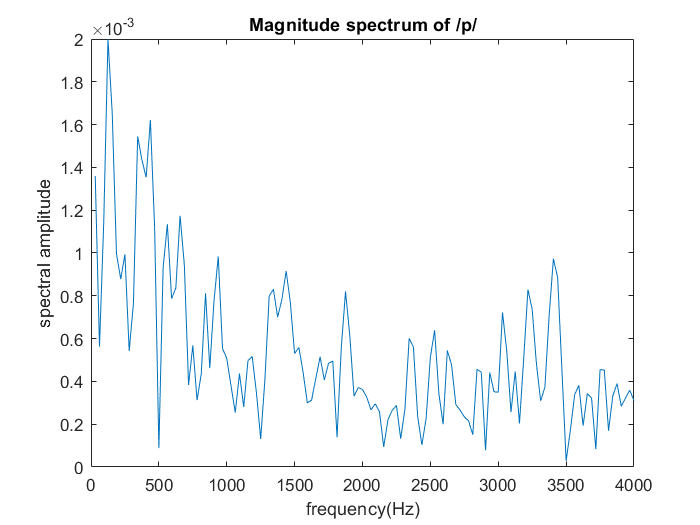


%sound-/p/
x=[1:256]*(8000/256);

Y8=abs(fft(y(1547:1656),256));

plot(x(1:128),Y8(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /p/');

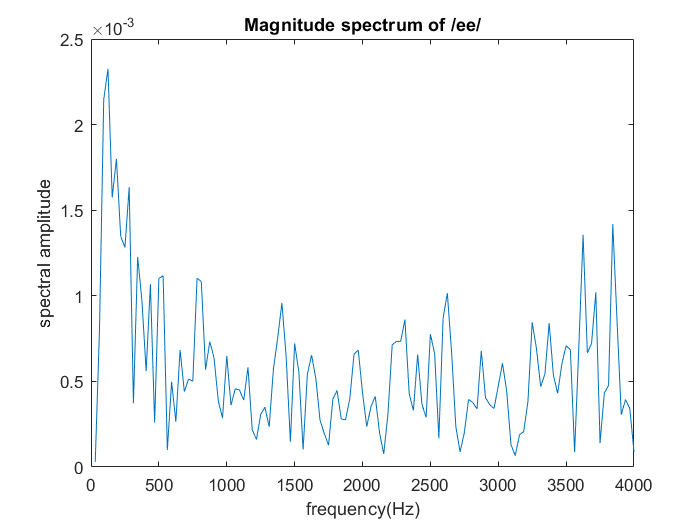


%sound-/ee/
x=[1:256]*(8000/256);

Y9=abs(fft(y(1656:1798),256));

plot(x(1:128),Y9(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /ee/');

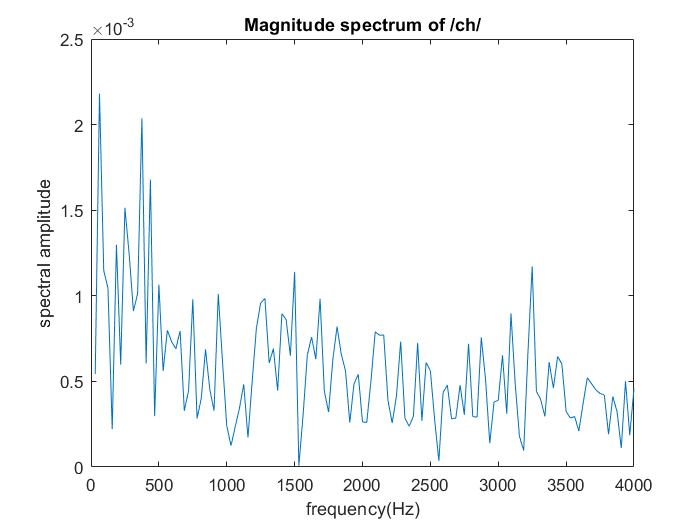


%sound-/ch/
x=[1:256]*(8000/256);

Y10=abs(fft(y(1798:1964),256));

plot(x(1:128),Y10(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /ch/');

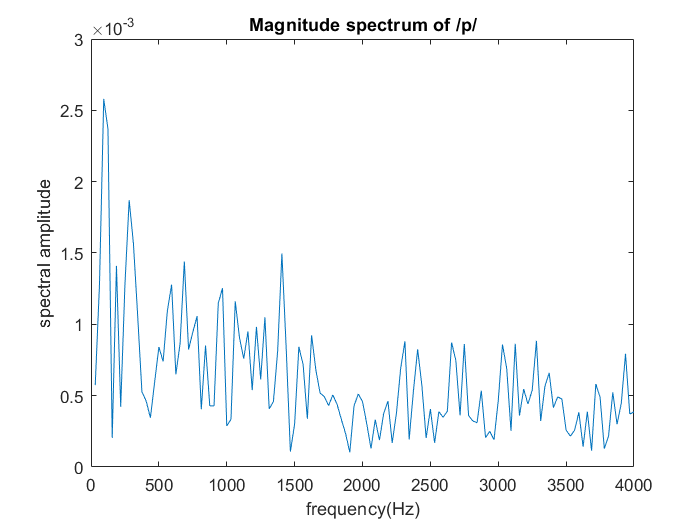


%sound-/p/
x=[1:256]*(8000/256);

Y11=abs(fft(y(1964:2103),256));

plot(x(1:128),Y11(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /p/');

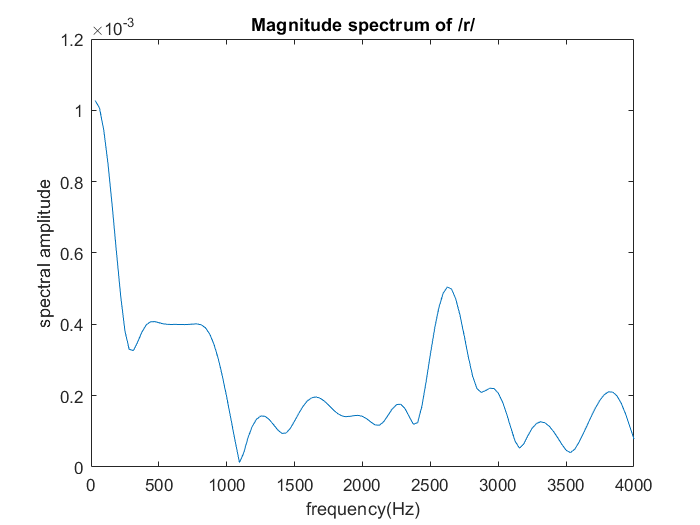


%sound-/r/
x=[1:256]*(8000/256);

Y12=abs(fft(y(2103:2134),256));

plot(x(1:128),Y12(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /r/');

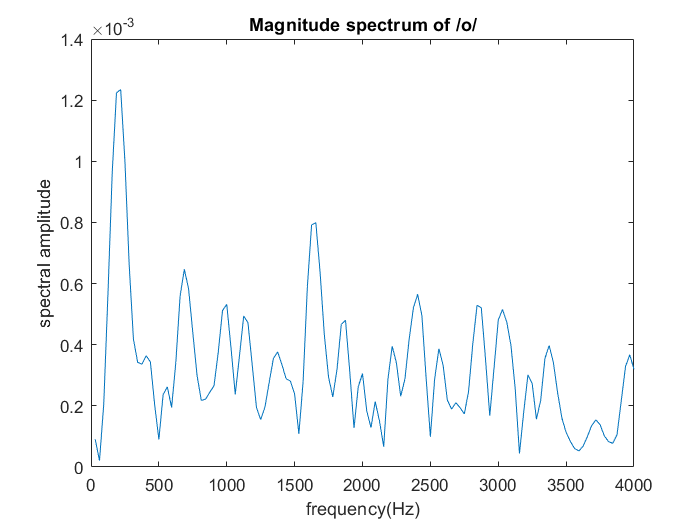


%sound-/o/
x=[1:256]*(8000/256);

Y13=abs(fft(y(2134:2208),256));

plot(x(1:128),Y13(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /o/');

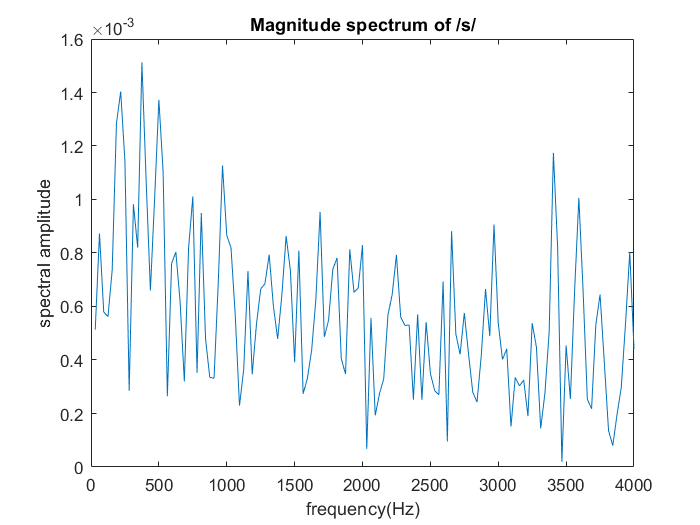


%sound-/s/
x=[1:256]*(8000/256);

Y14=abs(fft(y(2208:2349),256));

plot(x(1:128),Y14(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /s/');

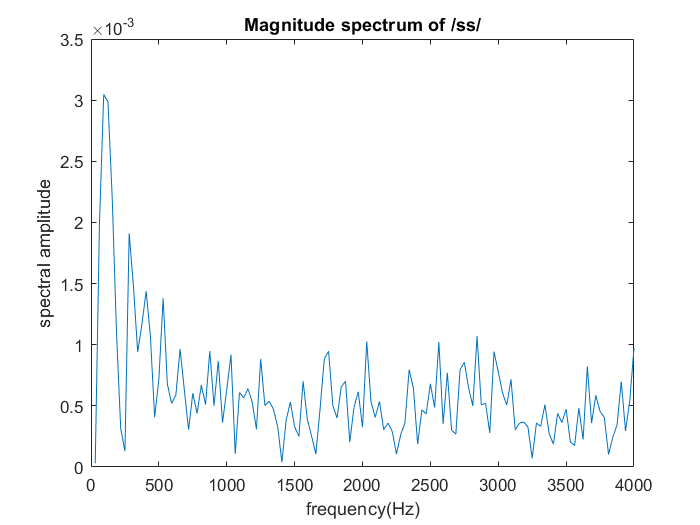


%sound-/ss/
x=[1:256]*(8000/256);

Y15=abs(fft(y(2349:2505),256));

plot(x(1:128),Y15(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /ss/');

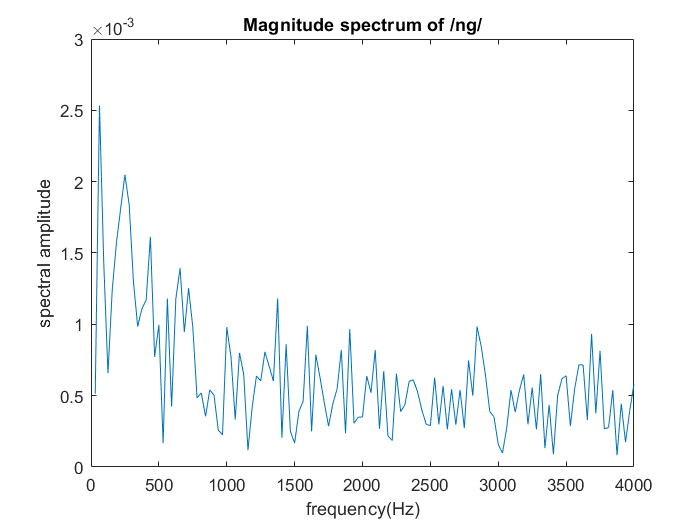


%sound-/ng/
x=[1:256]*(8000/256);

Y16=abs(fft(y(2505:2673),256));

plot(x(1:128),Y16(1:128));
xlabel('frequency(Hz)');
ylabel('spectral amplitude');
title('Magnitude spectrum of /ng/');

Observations:

By observing the magnitude spectrum plots of sounds, we see that voiced sounds like 'a', 'aa', 'ee','o','ng' have no peaks at frequency=0(DC value), as they have fundamental frequency and its harmonic components are produced by vocal cords (vocal folds). But we see peaks at frequency=0 incase of unvoiced sounds.

By observing the time domain plots, we see that voiced sounds are periodic in nature and unvoiced sounds are aperiodic as the vibration of vocal folds in voiced sounds are periodic in nature.